clear; close all; clc;
set(groot, 'defaultLegendInterpreter','latex'); 

## Defining Physical Parameters and Sensor Gains

The following lines of code will define the sensor gains and physical parameters used for the simulation.

Ka     = 5.1793;     % Power Amplifier
N      = 8.1;        % Speed Reduction Factor
Km     = 22.289;     % Motor gain [rad/s/V]
Km_lin = 19.763;     % Linearized motor gain [rad/s/V]
tau_m  = .2740;      % Motor time constant [s]
Kp     = 4.90379;    % Position Feedback Gain
Kt     = .1429;
vmo    = 0.66;       % Voltage to hold pendulum at 90 degrees [V]
g      = 9.81;       % gravitational acceleration [m/s/s]

#### Defining physical parameters of the pendulum

L = 0;      % Pendulum rod length [in]
m = 0; % Bob mass [kg]
physParam = [m, L, g, vmo, N];

The next line will define the intial condition of the pendulum

th_init = deg2rad(0);
Vin = 1.53;

git
simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step1Orig.csv");

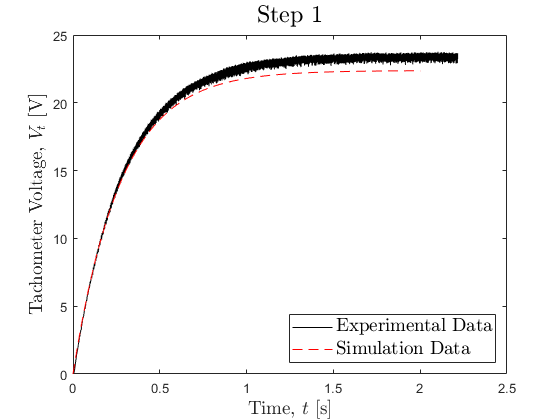

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 25]);
title('Step 1','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);


Vin = 1.6;

simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step2Orig.csv")

speed = 8192×3 table
    Time_s_     Channel2_V_    Math1_V_
    ________    ___________    ________

    -0.22382     -0.036574      0.04966
    -0.22357     -0.036574      0.04966
    -0.22332     -0.036574     0.053023
    -0.22307     -0.036574      0.04966
    -0.22282     -0.036574      0.04966
    -0.22257     -0.039932      0.04966
    -0.22232     -0.036574     0.046297
    -0.22207     -0.036574      0.04966
    -0.22182     -0.043291      0.04966
    -0.22157      -0.04665     0.056385
    -0.22132      -0.04665     0.053023
    -0.22107     -0.043291     0.053023
    -0.22082     -0.033215     0.039572
    -0.22057     -0.026498     0.029484
    -0.22032      -0.02314     0.026122
    -0.22007      -0.02314     0.026122


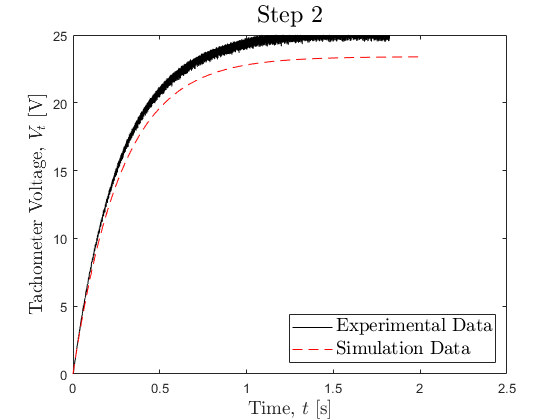

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 25]);
title('Step 2','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);



Vin = 1.06;

simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step3Orig.csv")

speed = 8192×3 table
    Time_s_     Channel2_V_     Math1_V_  
    ________    ___________    ___________

    -0.22391    0.00037049     -0.00077886
    -0.22366    0.00037049       0.0025837
    -0.22341    0.00037049       0.0025837
    -0.22316      0.030598        0.016034
    -0.22291      0.013805       0.0059463
    -0.22266      0.020522       0.0025837
    -0.22241      0.013805       0.0093089
    -0.22216     0.0037291        0.019397
    -0.22191     0.0037291        0.019397
    -0.22166    0.00037049        0.022759
    -0.22141    -0.0029881        0.026122
    -0.22116    -0.0063467        0.029484
    -0.22091    -0.0097052        0.029484
    -0.22066    -0.0097052        0.032847
    -0.22041    -0.0097052        0.032847
    -0.22016     -0.013064        0.032847


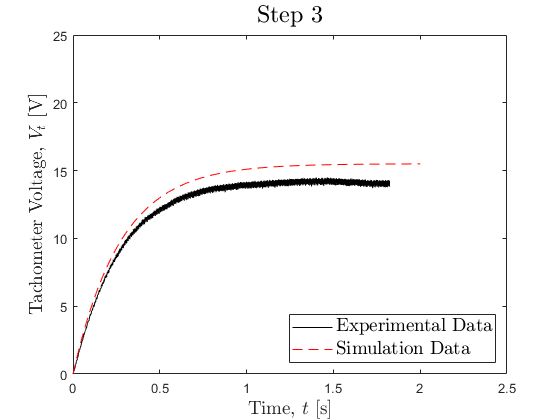

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 25]);
title('Step 3','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);